LB 2023 12 13. I have been running this script on Turbo because it's the only working copy of leaddbs-classic that I have access to. 

SUBJECT='DM10XX';
SESSION='intraop';

% this first part of this script is not task-specific
% TASK='lombard';

PATH_DATASET = 'Y:\DBS';
% PATH_DATASET = '/Volumes/Nexus4/DBS';

PATH_DER = [PATH_DATASET filesep 'derivatives'];
PATH_DER_SUB = [PATH_DER filesep 'sub-' SUBJECT];  
PATH_PREPROC = [PATH_DER_SUB filesep 'preproc'];
PATH_ANNOT = [PATH_DER_SUB filesep 'annot'];
PATH_SRC = [PATH_DATASET filesep 'sourcedata'];
PATH_SRC_SUB = [PATH_SRC filesep 'sub-' SUBJECT];   
PATH_RIPPLE = [PATH_SRC_SUB filesep 'ses-intraop' filesep 'ripple'];
PATH_ANALOG = [PATH_SRC_SUB filesep 'ses-intraop' filesep 'analog'];
PATH_ALHAOMEGA = [PATH_SRC_SUB filesep 'ses-intraop' filesep 'alphaomega']; %path to neuroomega's mpx files.
PATH_ALHAOMEGA_MAT = [PATH_ALHAOMEGA]; %path to neuroomega's converted mat files.
PATH_AUDIO_DER = [PATH_DER_SUB filesep 'aec']; %path to acoustic echo cancelling folder
PATHS_AUDIO_SRC = strcat(PATH_SRC_SUB,filesep,{'ses-training';'ses-preop';'ses-intraop'},filesep,'audio');
PATHS_TASK = strcat(PATH_SRC_SUB,filesep,{'ses-training';'ses-preop';'ses-intraop'},filesep,'task');
PATH_LEADDBS = [PATH_DER_SUB filesep 'Herrington_leaddbs_refined']; 

cd(PATH_PREPROC)

PATH_ECOGLOC = [PATH_DER_SUB filesep 'ecogloc'];
mkdir(PATH_ECOGLOC)

path_preopct_coreg = [PATH_ECOGLOC filesep 'leaddbs_coreg_preopct2preopmri']; mkdir(path_preopct_coreg)

copyfile([PATH_LEADDBS filesep 'anat_t1.nii'], [path_preopct_coreg filesep 'anat_t1.nii']); 

Copy preop ct from sourcedata. This path might need to be tweaked.  

copyfile([PATH_SRC_SUB filesep 'ses-intraop' filesep 'ct' filesep ...
               SUBJECT '_006_0.6_Soft_PRE_OP_Brain_DBS_FUNCTIONAL_.nii'], ...
         [path_preopct_coreg filesep 'postop_ct.nii']); 

which lead_dbs

C:\Program Files\LeadDBS_Classic\leaddbs\lead_dbs.m


^Ensure this says LeadDBS_Classic. This step has only been verified with the 'classic' (<v2.6, non-bids) version of lead-dbs. If it does not, remove the current Lead-DBS from your path and add a classic version. 

Open the lead_dbs gui. 

- Click 'choose patient directory' and navigate to the leaddbs_coreg_preopct2preopmri folder created above. 

- Check the 'coregister volumes' box and click 'Run'. 

                 Welcome to                            
                                                            
  _______________________________________                   
 /           ______     ___      _____   \                  
 | | ocali-  |         /   \    |     \  |             _______   
 | | zation  | lec     |   |    | BS   \ |          = / O   / \  
 | |         |---      /___\    | Sur- | |         = (   \./___) 
 | | of      | trodes |     |   | gery / |        =   \_ __ _)   
 | |_____    |_____   / fter \  |_____/  |         =   (O)(O)    
 \_______________________________________/                  
                                                            
                   Toolbox.                            
                     v2.6                    


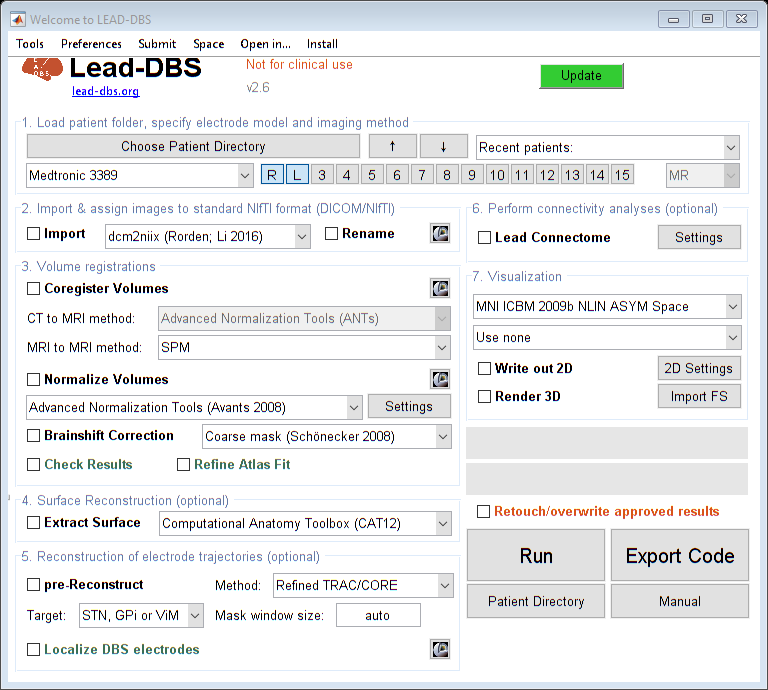

lead_dbs

Copy the registered preop/intraop CT (unfortunately called 'rpostop_ct.nii') into the ecogloc folder.  

copyfile([PATH_LEADDBS filesep 'anat_t1.nii'], [PATH_ECOGLOC filesep 'preop_mri.nii']); 
copyfile([PATH_LEADDBS filesep 'rpostop_ct.nii'], [PATH_ECOGLOC filesep 'rpostop_ct.nii']);
copyfile([path_preopct_coreg filesep 'rpostop_ct.nii'], [PATH_ECOGLOC filesep 'rpreop_ct.nii']);

Check that lead_dbs successfully co-registered the pre-op ct with your favorite imaging software (ITK-SNAP, slicer, etc).

LB 2023 12 13. I usually open the three files in ITK-SNAP--first the MRI, then the preop CT, then the postop CT. I check that the images are in alignment, that the preop CT is indeed the preop CT by looking for the frame artifacts. I also check the postop CT has DBS artifacts.